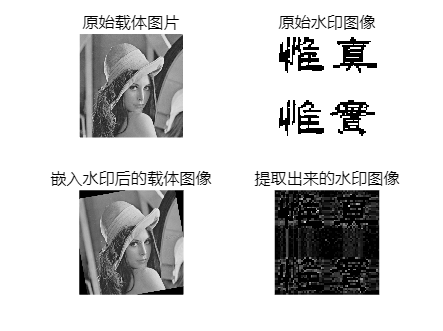

close all
clc
clear 


M = 512; % 原图像长度
N = 64; % 水印图像长度

alpha=0.05;% 嵌入强度系数
 
% 打开原图、水印图
I = imread('lena.jpg');
G = imread('水印(二值).bmp');

%W = zeros(M);
 
% 缩放、灰度化原图、改变精度
%I = imresize(I,[M M]);
%I = im2double(I); % double精度转换
%I = rgb2gray(I); % 灰度化处理
 
G = double(G) * 255; % 将逻辑值 1 转换为 255

% G = imresize(G,[N N]);
%G = uint8(G); % double精度转换
%G = rgb2gray(G); % 灰度化处理
 
subplot(2,2,1);
imshow(I);
title('原始载体图片');
subplot(2,2,2);
imshow(G,[]);
title('原始水印图像');
 
%Step 1
%对G进行SVD分解

[U,S,V] = svd(G);% 对G进行SVD分解，得到U、S、V矩阵
 

%Step 2
%进行2级离散小波变换
[LL1, LH1, HL1, HH1] = dwt2(I, 'haar');
[LL2, LH2, HL2, HH2] = dwt2(LL1, 'haar');%128*128


%Step 3
%选出最优嵌入块 
img=HH2;
% 初始化变量
img_size = [128 128];
sub_size = 64;
max_entropy = -Inf;
max_entropy_pos = [0, 0];
max_entropy_sub = [];

% 遍历图像中的所有64×64子片段
for i = 1:img_size(1) - sub_size + 1
    for j = 1:img_size(2) - sub_size + 1
        % 提取子片段
        sub_img = img(i:i+sub_size-1, j:j+sub_size-1);
   
        % 计算子片段的信息熵
        current_entropy = entropy(sub_img);
        
        % 更新最大信息熵及其位置
        if current_entropy > max_entropy
            max_entropy = current_entropy;
            max_entropy_pos = [i, j];
            max_entropy_sub = sub_img;
        end
    end
end

% %显示结果
% figure;
% subplot(1, 2, 1);
% imshow(img,[]);
% title('原图');
% rectangle('Position', [max_entropy_pos(2), max_entropy_pos(1), sub_size, sub_size], ...
%           'EdgeColor', 'r', 'LineWidth', 2);  % 标记最大信息熵的子片段位置
% 
% subplot(1, 2, 2);
% imshow(max_entropy_sub,[]);
% title(['最大熵子片段 (熵值: ', num2str(max_entropy), ')']);

%Step 4
%对最优嵌入块进行 DCT 变换，得到DCT系数矩阵 B
% m = floor(optimal_block_index/4)+1;
% n = mod(optimal_block_index, 4)+1
% x = (m - 1) * K + 1;
% y = (n - 1) * K + 1;
% 
i = max_entropy_pos(1);
j = max_entropy_pos(2);
 H_I = HH2(i:i+sub_size-1, j:j+sub_size-1);
% H_I = HH2(x:x+K-1, y:y+K-1);
%H_I = max_entropy_sub;

B = dct2(H_I);
 
%Step 5
%对B进行奇异值分解,嵌入水印
[U1,S1,V1] = svd(B);
S2 = S1 + alpha * S;
B1 = U1 * S2 * V1;
H_I = idct2(B1);
HH2(i:i+sub_size-1, j:j+sub_size-1) = H_I;
LL1 = idwt2(LL2,LH2,HL2,HH2,'haar');
W = idwt2(LL1,LH1,HL1,HH1,'haar');
W = uint8(W);
 
%攻击
%高斯滤波攻击
H = fspecial('gaussian',3,0.4);
W = imfilter(W,H);

%高斯噪声
% mean = 0; % 均值为0
% variance = 0.001; % 方差为0.01
% W = imnoise(W, 'gaussian', mean, variance);

%G 压缩攻击
% quality = 50;
% W = imresize(W, 0.5); % 缩小图像
% imwrite(W, 'temp.jpg', 'Quality', quality); % 保存为JPEG格式
% W = imread('temp.jpg'); % 重新读取JPEG图像
% W = imresize(W, 2); % 放大图像
 
% 剪切攻击
% r = 0.3; % 剪切比例为30%
% sz = size(W);
% h1 = round(sz(1)*r); % 剪切高度
% w1 = round(sz(2)*r); % 剪切宽度
% x1 = round(rand(sz(1)-h1)); % 随机选择一行
% y1 = round(rand(sz(2)-w1)); % 随机选择一列
% W(x1+1:x1+h1, y1+1:y1+w1) = 0; % 将指定区域置为0
 
% 旋转攻击
angle = 10; % 旋转角度为20度
W = imrotate(W, angle, 'bilinear', 'crop');


% W=imread("cameraman.tif");
% W = padarray(W, [256, 256], 'post');  % 在图像右侧和下方填充128像

%提取水印
[LL3, LH3, HL3, HH3] = dwt2(W, 'haar');
[LL4, LH4, HL4, HH4] = dwt2(LL3, 'haar');%128*128
H_I2 = HH4(i:i+sub_size-1, j:j+sub_size-1);
B2 = dct2(H_I2);
[Uw,Sw,Vw] = svd(B2);
Sx = (Sw - S1)/alpha;
B2 = U * Sx * V.';
A = B2;
%H_I2 = idct2(B2);
%A = idwt2(LL,LH,HL,H_I2,'haar');

 % threshold = 255/2; % 阈值范围为 [0, 1]
 % A = imbinarize(A, threshold);

% A = imbinarize(A); % 使用 Otsu 方法自动二值化

A = uint8(A);
subplot(2,2,3);
imshow(W);
title('嵌入水印后的载体图像');
subplot(2,2,4);
imshow(A,[]);
title('提取出来的水印图像');

 
% close all;
% subplot(2,2,1);
% imshow(H_I2);
% subplot(2,2,2);
% imshow(H);
% subplot(2,2,3);
% imshow(HH);


% 计算PSNR值
psnr_val = psnr(I, W);
 
% 显示PSNR值
fprintf('The PSNR value between the original image and reconstructed image is %f.\n', psnr_val);

The PSNR value between the original image and reconstructed image is 12.444285.


 
%显示NC值
C = normxcorr2(G, A);
% 提取最大相关系数值
nc_value = max(C(:));
% 输出结果
fprintf('归一化相关性（NC）值为：%.4f\n', nc_value);

归一化相关性（NC）值为：0.4187
